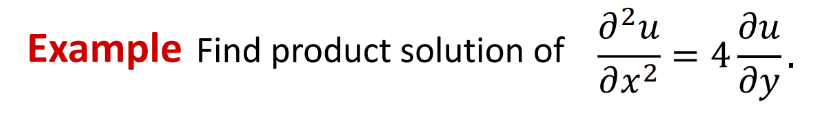

clear;
clc;
syms x y u(x,y) X(x) Y(y)

**PDE**

Eq = diff(u,x,2) == 4*diff(u,y)

$$Eq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=4\,\frac{\partial }{\partial y}u\left(x,y\right)$$

SepVar = subs(Eq,u(x,y),X(x)*Y(y))

$$SepVar(x, y) = Y\left(y\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=4\,X\left(x\right)\,\frac{\partial }{\partial y}Y\left(y\right)$$

**Separate variables of the equation**

SepVar = SepVar/(4*X(x)*Y(y))

$$SepVar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{4\,X\left(x\right)}=\frac{\frac{\partial }{\partial y}Y\left(y\right)}{Y\left(y\right)}$$

**Separate ODEs introduce constant (Lamda)^2**

syms lambda
eqX(x) = lhs(SepVar) == lambda

$$eqX(x) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{4\,X\left(x\right)}=\lambda$$

eqY(y) = rhs(SepVar) == lambda

$$eqY(y) = \frac{\frac{\partial }{\partial y}Y\left(y\right)}{Y\left(y\right)}=\lambda$$

**case 1 : Lamda = 0**

X(x) = dsolve(subs(eqX,lambda,0))

$$X(x) = C_{2}+C_{1}\,x$$

Y(y) = dsolve(subs(eqY,lambda,0))

$$Y(y) = C_{1}$$

U_0(x,y) = X(x)*Y(y) 

$$U\_0(x, y) = C_{1}\,\left(C_{2}+C_{1}\,x\right)$$

**case 2 : Lamda = -alpha^2 > 0, a > 0**

syms alpha C1 C2
X(x) = dsolve(subs(eqX,lambda,-alpha^2))

$$X(x) = C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x\,\mathrm{i}}$$

Y(y) = dsolve(subs(eqY,lambda,-alpha^2))

$$Y(y) = C_{1}\,{\mathrm{e}}^{-\alpha^{2}\,y}$$

U_N(x,y) = X(x)*Y(y)

$$U\_N(x, y) = C_{1}\,{\mathrm{e}}^{-\alpha^{2}\,y}\,\left(C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x\,\mathrm{i}}\right)$$

%simplify(rewrite(U_N,"sincos"))

**case 3 : Lamda = a^2 > 0, a > 0**

X(x) = dsolve(subs(eqX,lambda,alpha^2))

$$X(x) = C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x}$$

Y(y) = dsolve(subs(eqY,lambda,alpha^2))

$$Y(y) = C_{1}\,{\mathrm{e}}^{\alpha^{2}\,y}$$

U_N(x,y) = X(x)*Y(y)

$$U\_N(x, y) = C_{1}\,{\mathrm{e}}^{\alpha^{2}\,y}\,\left(C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x}\right)$$

**buildHeatStruct**

function u_n = buildHeatStruct
syms t x n b_n L D u_n(x,t,n) lambda(n)
assume(n,"integer")
assum([L,D],"positive")
lambda(n) = n*pi/L;
u_n(x,t,n) = b_n.*sin(x*lambda(n)).*exp(-t*D*lambda(n).^2);
end